fx = @(t) 16 * (sin(t)).^3;
fy = @(t) 13 * cos(t) - 5 * cos(2 * t) - 2 * cos(3 * t) - cos(4 * t)

fy = function_handle with value:
    @(t)13*cos(t)-5*cos(2*t)-2*cos(3*t)-cos(4*t)


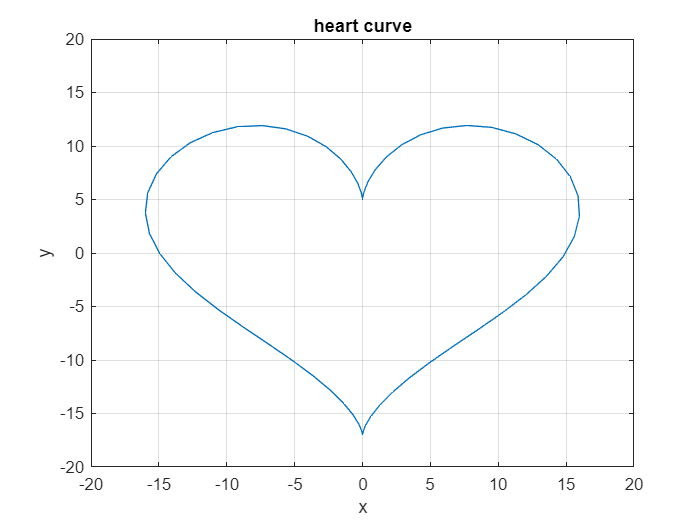

p = 2 * pi;
t = [0:.1:p];
y = fy(t);
x = fx(t);
plot(x,y);
grid on;
xlim([-20 20]);
ylim([-20 20]);
title('heart curve')
xlabel('x');
ylabel('y');



datx= [0 0.5 2 4];
daty= [1 exp(0.5) exp(2) exp(4)];
[a,b,c,d]= cubic_spline_coefs(datx,daty);